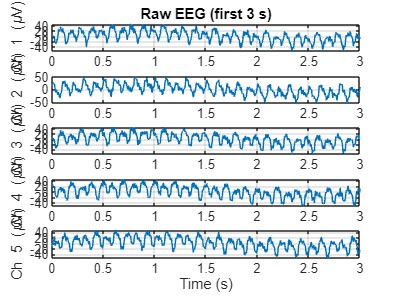

%% EXERCISE 1: Load and inspect EEG data
clear; clc; close all;

% --- Option A: Load real EEG (uncomment if available) ---
% load('EEG_Sample.mat');   % should contain: eeg (channels x samples), Fs
% Fs = 160;

% --- Option B: Generate synthetic EEG (5 channels, 10 s @ 250 Hz) ---
Fs = 250;                    % Sampling frequency (Hz)
T  = 10;                     % Duration (s)
t  = 0:1/Fs:T-1/Fs;
N  = length(t);
numCh = 5;

rng(42);                     % Reproducible
synthetic = zeros(numCh, N);
for ch = 1:numCh
    alpha = 20*sin(2*pi*10*t + rand*2*pi);          % 10 Hz alpha
    beta  = 8 *sin(2*pi*20*t + rand*2*pi);          % 20 Hz beta
    theta = 10*sin(2*pi*6 *t + rand*2*pi);          % 6 Hz theta
    drift = 15*sin(2*pi*0.3*t);                     % slow drift
    noise = 4*randn(1,N);                           % white noise
    line  = 6*sin(2*pi*50*t);                       % power line
    synthetic(ch,:) = alpha + beta + theta + drift + noise + line;
end
eeg = synthetic;

% Plot raw EEG (all channels)
figure('Name','Raw EEG','Color','w');
for ch = 1:numCh
    subplot(numCh,1,ch);
    plot(t, eeg(ch,:));
    ylabel(sprintf('Ch %d (\\muV)', ch));
    grid on; xlim([0 3]);
    if ch == 1, title('Raw EEG (first 3 s)'); end
    if ch == numCh, xlabel('Time (s)'); end
end

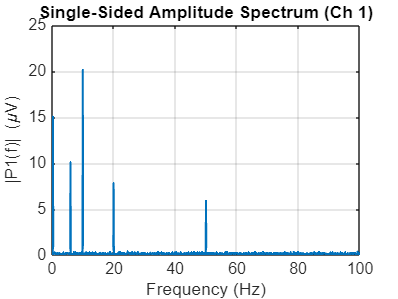

%% EXERCISE 2: PSD via FFT
ch = 1;                        % Analyse channel 1
x  = eeg(ch,:);
L  = length(x);

Y  = fft(x);
P2 = abs(Y/L);
P1 = P2(1:floor(L/2)+1);
P1(2:end-1) = 2*P1(2:end-1);
f  = Fs*(0:floor(L/2))/L;

figure('Name','FFT Spectrum','Color','w');
plot(f, P1, 'LineWidth', 1.2);
xlabel('Frequency (Hz)'); ylabel('|P1(f)| (\muV)');
title('Single-Sided Amplitude Spectrum (Ch 1)');
xlim([0 100]); grid on;

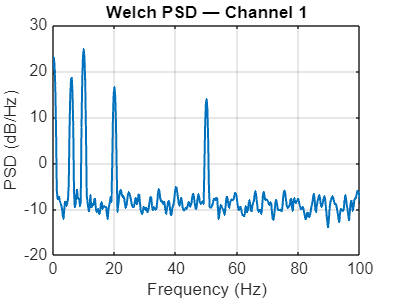

%% EXERCISE 3: Welch PSD
window   = hamming(2*Fs);         % 2 s window
noverlap = round(0.5*length(window));
nfft     = 1024;

[Pxx, fw] = pwelch(x, window, noverlap, nfft, Fs);

figure('Name','Welch PSD','Color','w');
plot(fw, 10*log10(Pxx), 'LineWidth', 1.2);
xlabel('Frequency (Hz)'); ylabel('PSD (dB/Hz)');
title('Welch PSD — Channel 1');
grid on; xlim([0 100]);

%% EXERCISE 4: Band power computation
bands = { 'Delta',[0.5 4]; 'Theta',[4 8]; 'Alpha',[8 13];
          'Beta', [13 30]; 'Gamma',[30 45] };

fprintf('\nBand power (Ch 1) using Welch PSD:\n');


Band power (Ch 1) using Welch PSD:


fprintf('%-8s %-12s %-12s\n','Band','Range (Hz)','Power (dB)');

Band     Range (Hz)   Power (dB)  


totalPower = bandpower(Pxx, fw, [0.5 45], 'psd');

for b = 1:size(bands,1)
    name = bands{b,1};
    rng_ = bands{b,2};
    bp   = bandpower(Pxx, fw, rng_, 'psd');
    rel  = 100*bp/totalPower;
    fprintf('%-8s %-12s %-12.2f  (%.1f%%)\n', ...
        name, sprintf('%.1f-%.1f',rng_(1),rng_(2)), 10*log10(bp), rel);
end

Delta    0.5-4.0      16.76         (14.1%)
Theta    4.0-8.0      17.15         (15.4%)
Alpha    8.0-13.0     23.08         (60.3%)
Beta     13.0-30.0    15.15         (9.7%)
Gamma    30.0-45.0    3.26          (0.6%)


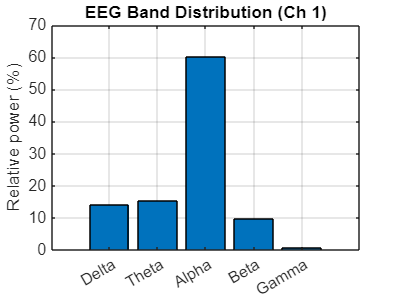


% Bar plot of relative band power
relP = zeros(size(bands,1),1);
for b = 1:size(bands,1)
    relP(b) = 100*bandpower(Pxx, fw, bands{b,2}, 'psd')/totalPower;
end
figure('Name','Band Power','Color','w');
bar(relP); set(gca,'XTickLabel',bands(:,1));
ylabel('Relative power (%)'); title('EEG Band Distribution (Ch 1)');
grid on;

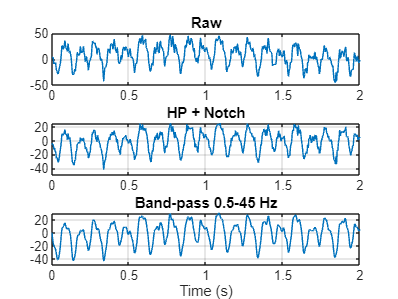

%% EXERCISE 5: Filtering
% High-pass Butterworth (order 4)
hp = designfilt('highpassiir','FilterOrder',4, ...
                'PassbandFrequency',0.5,'SampleRate',Fs);

% Notch at 50 Hz
wo = 50/(Fs/2); bw = wo/35;
[bN,aN] = iirnotch(wo, bw);

% Band-pass (order 4)
bp = designfilt('bandpassiir','FilterOrder',4, ...
                'HalfPowerFrequency1',0.5,'HalfPowerFrequency2',45, ...
                'SampleRate',Fs);

x_hp    = filtfilt(hp, x);
x_notch = filtfilt(bN, aN, x_hp);
x_bp    = filtfilt(bp, x);

figure('Name','Filtering','Color','w');
subplot(3,1,1); plot(t, x);       title('Raw');           xlim([0 2]); grid on;
subplot(3,1,2); plot(t, x_notch); title('HP + Notch');    xlim([0 2]); grid on;
subplot(3,1,3); plot(t, x_bp);    title('Band-pass 0.5-45 Hz'); xlim([0 2]); grid on;
xlabel('Time (s)');

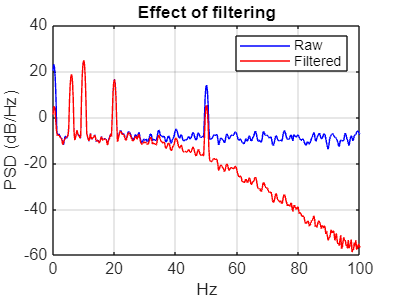


% Verify with PSD
[Pxx_f, fw_f] = pwelch(x_bp, window, noverlap, nfft, Fs);
figure('Name','PSD before/after','Color','w');
plot(fw,  10*log10(Pxx),   'b'); hold on;
plot(fw_f,10*log10(Pxx_f), 'r');
legend('Raw','Filtered'); xlabel('Hz'); ylabel('PSD (dB/Hz)');
title('Effect of filtering'); grid on; xlim([0 100]);

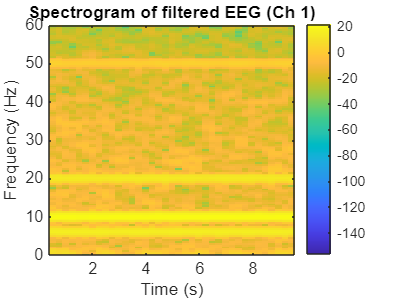

%% EXERCISE 6: STFT / Spectrogram
win_s  = 1;                        % 1 s window
nwin   = round(win_s*Fs);
nov    = round(0.75*nwin);
nfft2  = 512;

figure('Name','Spectrogram','Color','w');
spectrogram(x_bp, hamming(nwin), nov, nfft2, Fs, 'yaxis');
title('Spectrogram of filtered EEG (Ch 1)');
ylim([0 60]); colorbar;

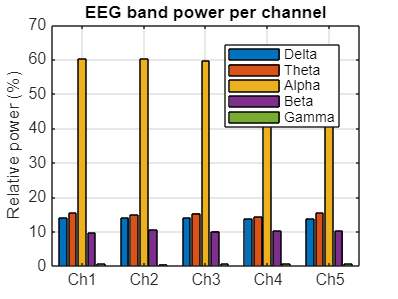

%% EXERCISE 7: Band power across channels

% Re-define Welch parameters in case this section is run standalone
window   = hamming(2*Fs);
noverlap = round(0.5*length(window));
nfft     = 1024;

% Build matrix: rows = channels, columns = bands
relP_ch = zeros(numCh, size(bands,1));
for ch = 1:numCh
    [Pxx_ch, fw_ch] = pwelch(eeg(ch,:), window, noverlap, nfft, Fs);
    tot = bandpower(Pxx_ch, fw_ch, [0.5 45], 'psd');
    for b = 1:size(bands,1)
        relP_ch(ch,b) = 100*bandpower(Pxx_ch, fw_ch, bands{b,2}, 'psd')/tot;
    end
end

figure('Name','Channel comparison','Color','w');
bar(relP_ch,'grouped');
set(gca,'XTickLabel', arrayfun(@(c) sprintf('Ch%d',c), 1:numCh, 'uni',0));
legend(bands(:,1),'Location','best');
ylabel('Relative power (%)'); title('EEG band power per channel');
grid on;